## Project Goal: Analyzing Career Trajectory of Great Hitters

Free agency is one of the most important, and exciting, times for baseball teams. It offers hope for franchises to sign marquee players to long-term deals. But make a mistake, and your team could lack money to sign young stars or future free agents for years. 

Projecting a player's production into the future is difficult. One tool used for this problem is to examine the career trajectory of similar players. In this project, we'll look at the great hitters throughout baseball history and find their typical OPS for each year in the league. We'll find peak seasons for these hitters and make comparisons with other players. At the end of the project, We'll have table and plot similar to the images below. Best of all, you'll gain skills to answer a number of different questions. 

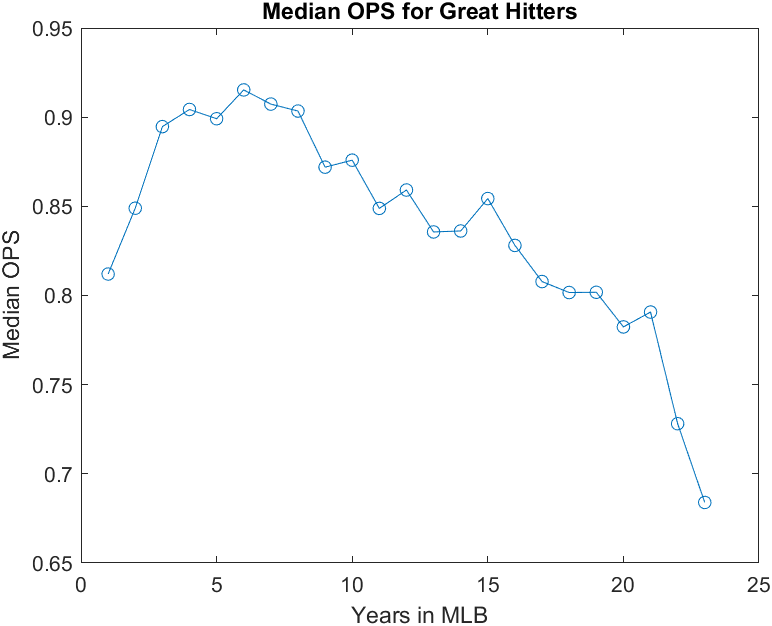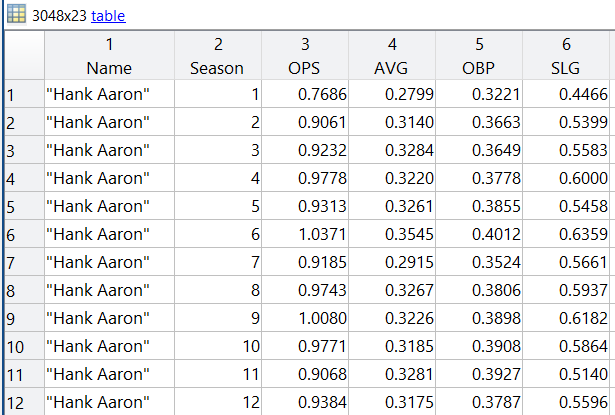

### **Downloading the data**

We'll be using the [Lahman Database](http://www.seanlahman.com/baseball-archive/statistics/) for this project. The Lahman Data base contains historical data for every season back to 1871.

### Setup the Lahman Database

The function below will download the database and place it on your MATLAB Search Path for you. 

setupLahmanDatabase

### Import the Batting Table

Create an import function for the Batting.csv file using the Import Tool

batting = ImportBattingTable("Batting.csv")

batting = 110495×19 table
    playerID     yearID    G     AB     R     H     x2B    x3B    HR    RBI    SB    CS    BB    SO    IBB    HBP    SH     SF     GIDP
    _________    ______    __    ___    __    __    ___    ___    __    ___    __    __    __    __    ___    ___    ___    ___    ____

    abercda01     1871      1      4     0     0     0 

### Explore the Batting Table

Use the tools in the Live Editor to quickly explore the data

batting = sortrows(batting, "HR", "descend")

batting = 110495×19 table
    playerID     yearID     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS     BB     SO     IBB    HBP    SH    SF     GIDP
    _________    ______    ___    ___    ___    ___    ___    ___    __    ___    __    ___    ___    ___    ___    ___    __    ___    ____

    bondsba01     2001     153    476    129 

batting = batting(~ismissing(batting.IBB),:);
batting = sortrows(batting, "IBB", "descend")

batting = 73845×19 table
    playerID     yearID     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB     SO     IBB    HBP    SH    SF    GIDP
    _________    ______    ___    ___    ___    ___    ___    ___    __    ___    __    __    ___    ___    ___    ___    __    __    ____

    bondsba01     2004     147    373    129    13

### **Beginning Analysis**

To analyze players' OPS per season in the league, we need their cumulative season statistics. To determine players with "great" hitting careers, we need the career statistics. In this task you will create these two tables.

### Calculate Career Statistics

For every playerID in the batting table, you need to sum their statistics to get the career stats. You can think of grouping the data by the playerID and summing the data for each group. Use the "Compute by Group" Live Task to do this. Confirm your work by looking at some key players.

% Compute group summary
newTable = groupsummary(batting,"playerID","sum");
newTable.GroupCount = []

newTable = 12579×19 table
    playerID     sum_yearID    sum_G    sum_AB    sum_R    sum_H    sum_x2B    sum_x3B    sum_HR    sum_RBI    sum_SB    sum_CS    sum_BB    sum_SO    sum_IBB    sum_HBP    sum_SH    sum_SF    sum_GIDP
    _________    __________    _____    ______    _____    _____    _______    _______    ______    _______    ______    ______    ______    ______    _______    _______    

#### Modify Variables in the Career Table

Notice that the operation also summed the year in the yearID variable. This doesn't have meaning, so remove it from the table.

careerBatting = newTable;
careerBatting = removevars(careerBatting, "sum_yearID")

careerBatting = 12579×18 table
    playerID     sum_G    sum_AB    sum_R    sum_H    sum_x2B    sum_x3B    sum_HR    sum_RBI    sum_SB    sum_CS    sum_BB    sum_SO    sum_IBB    sum_HBP    sum_SH    sum_SF    sum_GIDP
    _________    _____    ______    _____    _____    _______    _______    ______    _______    ______    ______    ______    ______    _______    _______    ______    ______    

### Calculate Season Statistics

Calculating Season stats is similar to the career stats except we need to use both playerID and yearID to group the data. This is to calculate the sum of all the "stints" for players traded during the season.

% Compute group summary
newTable2 = groupsummary(batting,["playerID","yearID"],"sum")

newTable2 = 68162×20 table
    playerID     yearID    GroupCount    sum_G    sum_AB    sum_R    sum_H    sum_x2B    sum_x3B    sum_HR    sum_RBI    sum_SB    sum_CS    sum_BB    sum_SO    sum_IBB    sum_HBP    sum_SH    sum_SF    sum_GIDP
    _________    ______    __________    _____    ______    _____    _____    _______    _______    ______    _______    ______    ______    ______    ______    

#### Confirm Your Work

Look for a player you know was traded and confirm that the data in the batting table was summed to season statistics. Also, Focusing on just 1 player (Oliver Drake) to see personal stats.

seasonBatting = newTable2;
seasonBatting = renamevars(seasonBatting, "GroupCount", "NumbTeams")

seasonBatting = 68162×20 table
    playerID     yearID    NumbTeams    sum_G    sum_AB    sum_R    sum_H    sum_x2B    sum_x3B    sum_HR    sum_RBI    sum_SB    sum_CS    sum_BB    sum_SO    sum_IBB    sum_HBP    sum_SH    sum_SF    sum_GIDP
    _________    ______    _________    _____    ______    _____    _____    _______    _______    ______    _______    ______    ______    ______    ______    

olDrake = batting(batting.playerID=="drakeol01", :)

olDrake = 11×19 table
    playerID     yearID    G     AB    R    H    x2B    x3B    HR    RBI    SB    CS    BB    SO    IBB    HBP    SH    SF    GIDP
    _________    ______    __    __    _    _    ___    ___    __    ___    __    __    __    __    ___    ___    __    __    ____

    drakeol01     2015     13    0     0    0     0      0     0     

### **Deeper Calculations**

We don't see variables like "sum_HR" on TV broadcasts or baseball cards, and we don't refer to players by their playerIDs. Our current tables also don't include OPS or other common stats like AVG, OBP, and SLG. In this task, you'll calculate and add additional statistics to the tables. You'll modify variable names to match standard convention and add the players' names to the table.

### Change Variable Names to Remove "sum_"

#### Start with Season Table

Access the variable names in a table like so:  varnames = `tablename.Properties.VariableNames`

varnames = seasonBatting.Properties.VariableNames

varnames = 1×20 cell array
    {'playerID'}    {'yearID'}    {'NumbTeams'}    {'sum_G'}    {'sum_AB'}    {'sum_R'}    {'sum_H'}    {'sum_x2B'}    {'sum_x3B'}    {'sum_HR'}    {'sum_RBI'}    {'sum_SB'}    {'sum_CS'}    {'sum_BB'}    {'sum_SO'}    {'sum_IBB'}    {'sum_HBP'}    {'sum_SH'}    {'sum_SF'}    {'sum_GIDP'}


varnames = erase(varnames, "sum_")

varnames = 1×20 cell array
    {'playerID'}    {'yearID'}    {'NumbTeams'}    {'G'}    {'AB'}    {'R'}    {'H'}    {'x2B'}    {'x3B'}    {'HR'}    {'RBI'}    {'SB'}    {'CS'}    {'BB'}    {'SO'}    {'IBB'}    {'HBP'}    {'SH'}    {'SF'}    {'GIDP'}


seasonBatting.Properties.VariableNames = varnames

seasonBatting = 68162×20 table
    playerID     yearID    NumbTeams     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB    SO    IBB    HBP    SH    SF    GIDP
    _________    ______    _________    ___    ___    ___    ___    ___    ___    __    ___    __    __    __    __    ___    ___    __    __    ___

#### Repeat for the Career Table

varnames = careerBatting.Properties.VariableNames;
varnames = erase(varnames, "sum_");
careerBatting.Properties.VariableNames = varnames

careerBatting = 12579×18 table
    playerID      G       AB       R       H      x2B    x3B    HR     RBI     SB     CS     BB      SO     IBB    HBP    SH    SF     GIDP
    _________    ____    _____    ____    ____    ___    ___    ___    ____    ___    __    ____    ____    ___    ___    __    ___    ____

    aardsda01     331        4       0       0      0     0       0       0 

### Add AVG, SLG, OBP, and OPS to the Tables

#### Calculate Batting Average

seasonBatting.AVG = seasonBatting.H ./ seasonBatting.AB

seasonBatting = 68162×21 table
    playerID     yearID    NumbTeams     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB    SO    IBB    HBP    SH    SF    GIDP      AVG  
    _________    ______    _________    ___    ___    ___    ___    ___    ___    __    ___    __    __    __    __    ___    ___    __    

careerBatting.AVG = careerBatting.H ./ careerBatting.AB

careerBatting = 12579×19 table
    playerID      G       AB       R       H      x2B    x3B    HR     RBI     SB     CS     BB      SO     IBB    HBP    SH    SF     GIDP      AVG   
    _________    ____    _____    ____    ____    ___    ___    ___    ____    ___    __    ____    ____    ___    ___    __    ___    ____    ________

    aardsda01     

#### Calculate SLG, OBP, and OPS for the Season Table

Calculate these stats with the following equations:

$\textrm{OBP}=\frac{\mathrm{H}+\textrm{BB}+\textrm{HBP}}{\textrm{AB}+\textrm{BB}+\textrm{HBP}+\textrm{SF}}$;  $\textrm{SLG}=\frac{\mathrm{H}+2\mathrm{B}+2\times 3\mathrm{B}+3\times \textrm{HR}\;}{\textrm{AB}}$;  $\textrm{OPS}=\textrm{OBP}+\textrm{SLG}$ 

seasonBatting.OBP = (seasonBatting.H + seasonBatting.BB + seasonBatting.HBP)...
    ./ (seasonBatting.AB + seasonBatting.BB + seasonBatting.HBP + seasonBatting.SF);

seasonBatting.SLG = (seasonBatting.H + seasonBatting.x2B + 2*seasonBatting.x3B...
    + 3*seasonBatting.HR) ./ seasonBatting.AB;

seasonBatting.OPS = seasonBatting.OBP + seasonBatting.SLG

seasonBatting = 68162×24 table
    playerID     yearID    NumbTeams     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB    SO    IBB    HBP    SH    SF    GIDP      AVG        OBP        SLG        OPS  
    _________    ______    _________    ___    ___    ___    ___    ___    ___    __    ___    __    __    __    __

#### Repeat for the Career Table

careerBatting.OBP = (careerBatting.H + careerBatting.BB + careerBatting.HBP)...
    ./ (careerBatting.AB + careerBatting.BB + careerBatting.HBP + careerBatting.SF);

careerBatting.SLG = (careerBatting.H + careerBatting.x2B + 2*careerBatting.x3B + ...
    3*careerBatting.HR) ./ careerBatting.AB;

careerBatting.OPS = careerBatting.OBP + careerBatting.SLG

careerBatting = 12579×22 table
    playerID      G       AB       R       H      x2B    x3B    HR     RBI     SB     CS     BB      SO     IBB    HBP    SH    SF     GIDP      AVG         OBP         SLG         OPS  
    _________    ____    _____    ____    ____    ___    ___    ___    ____    ___    __    ____    ____    ___    ___    __    

### Add Player Names to the Tables

#### Import Names from the People Table

names = importNames("People.csv")

names = 20673×3 table
    playerID     nameFirst       nameLast   
    _________    __________    _____________

    aardsda01    "David"       "Aardsma"    
    aaronha01    "Hank"        "Aaron"      
    aaronto01    "Tommie"      "Aaron"      
    aasedo01     "Don"         "Aase"       
    abadan01     "Andy"        "Abad"       
    abadfe01     "Fernando"    "Abad"       
    abadijo01    "John"        "Abadie"     
    abbated01    "Ed"          "Abbaticchio"
    abbeybe01    "Bert"        "Abbey"      
    abbeych01    "Charlie"     "Abbey"      
    abbotco01    "Cory"        "Abbott"     
    abbotda01    "Dan"         "Abbott"     
    abbotfr01    "Fred"        "Abbott"     
    abbotgl01    "Glenn"       "Abbott"     
    abbotje01    "Jeff"        "Abbott"     
    abbotji01    "Jim"         "Abbott"     


#### Modify Table to Combine First and Last Name

names.Name = names.nameFirst + " " + names.nameLast

names = 20673×4 table
    playerID     nameFirst       nameLast             Name      
    _________    __________    _____________    ________________

    aardsda01    "David"       "Aardsma"        "David Aardsma" 
    aaronha01    "Hank"        "Aaron"          "Hank Aaron"    
    aaronto01    "Tommie"      "Aaron"          "Tommie Aaron"  
    aasedo01     "Don"         "Aase"           "Don Aase"      
    abadan01     "Andy"        "Abad"           "Andy Abad"     
    abadfe01     "Fernando"    "Abad"           "Fernando Abad" 
    abadijo01    "John"        "Abadie"         "John Abadie"   
    abbated01    "Ed"          "Abbaticchio"    "Ed Abbaticchio"
    abbeybe01    "Bert"        "Abbey"          "Bert Abbey"    
    abbeych01    "Charlie"     "Abbey"          "Charlie Abbey" 
    abbotco01    "Cory"        "Abbott"         "Cory Abbott"

names = removevars(names, ["nameFirst", "nameLast"])

names = 20673×2 table
    playerID           Name      
    _________    ________________

    aardsda01    "David Aardsma" 
    aaronha01    "Hank Aaron"    
    aaronto01    "Tommie Aaron"  
    aasedo01     "Don Aase"      
    abadan01     "Andy Abad"     
    abadfe01     "Fernando Abad" 
    abadijo01    "John Abadie"   
    abbated01    "Ed Abbaticchio"
    abbeybe01    "Bert Abbey"    
    abbeych01    "Charlie Abbey" 
    abbotco01    "Cory Abbott"   
    abbotda01    "Dan Abbott"    
    abbotfr01    "Fred Abbott"   
    abbotgl01    "Glenn Abbott"  
    abbotje01    "Jeff Abbott"   
    abbotji01    "Jim Abbott"    


#### Join the Names to the Season Table

% Join tables
joinedData = outerjoin(seasonBatting,names,"Type","left","Keys","playerID",...
    "MergeKeys",true)

joinedData = 68162×25 table
    playerID     yearID    NumbTeams     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB    SO    IBB    HBP    SH    SF    GIDP      AVG        OBP        SLG        OPS           Name      
    _________    ______    _________    ___    ___    ___    ___    ___    ___    __    ___    __    __    

seasonBatting = joinedData;

#### Repeat the Join with the Career Table

% Join tables
joinedData2 = outerjoin(careerBatting,names,"Type","left","Keys","playerID",...
    "MergeKeys",true)

joinedData2 = 12579×23 table
    playerID      G       AB       R       H      x2B    x3B    HR     RBI     SB     CS     BB      SO     IBB    HBP    SH    SF     GIDP      AVG         OBP         SLG         OPS              Name        
    _________    ____    _____    ____    ____    ___    ___    ___    ____    ___    __    ____    ____    ___    ___

careerBatting = joinedData2;

### Rearrange Table Variables 

seasonBatting = movevars(seasonBatting, ["Name", "OPS", "AVG", "SLG", "OBP"], "After", "playerID")

seasonBatting = 68162×25 table
    playerID          Name            OPS        AVG        SLG        OBP      yearID    NumbTeams     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB    SO    IBB    HBP    SH    SF    GIDP
    _________    _______________    _______    _______    _______    _______    ______    _________    ___    ___    ___    ___


careerBatting = movevars(careerBatting, ["Name", "OPS", "AVG", "SLG", "OBP"], "After", "playerID")

careerBatting = 12579×23 table
    playerID             Name              OPS        AVG         SLG         OBP        G       AB       R       H      x2B    x3B    HR     RBI     SB     CS     BB      SO     IBB    HBP    SH    SF     GIDP
    _________    ____________________    _______    ________    ________    ________    ____    _____    ____    ____    ___    ___    ___    

### Save Your Work

save seasonBatting3 seasonBatting
save careerBatting3 careerBatting

## Exploring the Data

### Explore OPS

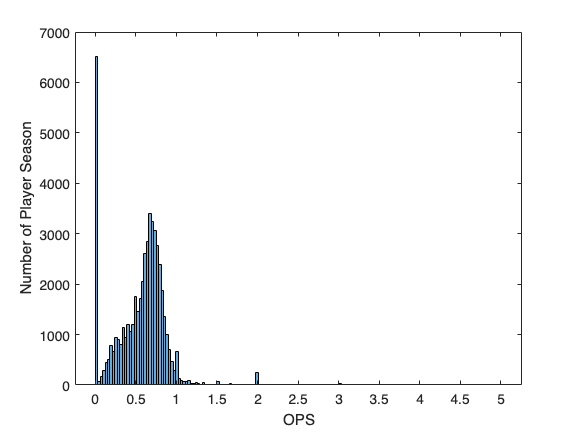

histogram(seasonBatting.OPS);
xlabel("OPS")
ylabel("Number of Player Season")

### **Copying and Exploring OPS Stats Table**

seasonOPS = seasonBatting;

seasonOPS = seasonOPS(~ismissing(seasonOPS.OPS),:);
seasonOPS = sortrows(seasonOPS, "OPS", "descend");
seasonOPS = seasonOPS(seasonOPS.AB >= 150 | ismissing(seasonOPS.AB),:)

seasonOPS = 20848×25 table
    playerID          Name           OPS        AVG        SLG        OBP      yearID    NumbTeams     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB     SO     IBB    HBP    SH    SF    GIDP
    _________    _______________    ______    _______    _______    _______    ______    _________    ___    ___    ___    ___    

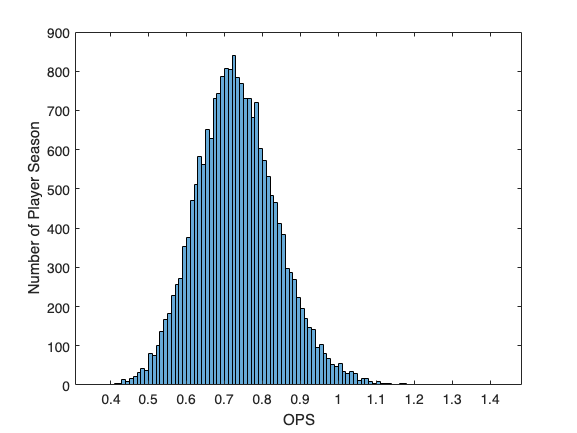

histogram(seasonOPS.OPS);
xlabel("OPS")
ylabel("Number of Player Season")

### Examine HR and SO

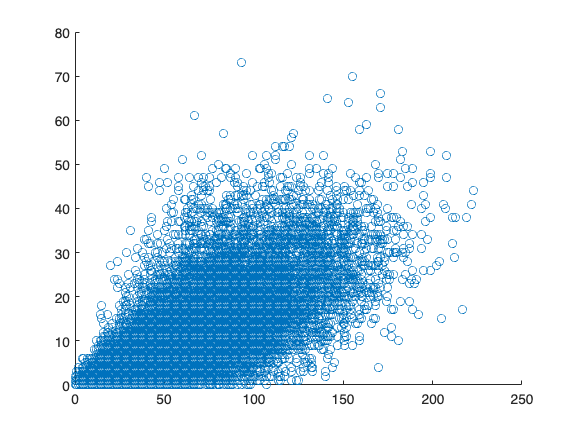

scatter(seasonBatting.SO, seasonBatting.HR)


amazingSeason = seasonBatting(seasonBatting.HR >= 30 & (seasonBatting.HR > seasonBatting.SO), :)

amazingSeason = 4×25 table
    playerID           Name            OPS        AVG        SLG        OBP      yearID    NumbTeams     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB     SO    IBB    HBP    SH    SF    GIDP
    _________    ________________    _______    _______    _______    _______    ______    _________    ___    ___    ___    ___ 

## **Table of Great Hitters**

### Define Minimum Career Stats for Players to Investigate

There are many metrics you might use to define a player who was, or is, a great hitter. Here, we'll use a minimum of 3000 career AB and a career OPS greater than 0.830. But, you can choose your own criteria as well!

minAB = 3000;
minOPS = 0.83;
greatCareers = careerBatting(careerBatting.AB >= minAB & careerBatting.OPS >= minOPS, :)

greatCareers = 154×23 table
    playerID           Name            OPS        AVG        SLG        OBP       G       AB       R       H      x2B    x3B    HR     RBI     SB     CS      BB      SO     IBB    HBP    SH    SF     GIDP
    _________    ________________    _______    _______    _______    _______    ____    _____    ____    ____    ___    ___    ___    ____

### Create Table of Season Stats with Only Great Hitters

greatHitters = seasonBatting(ismember(seasonBatting.playerID, greatCareers.playerID),:)

greatHitters = 2343×25 table
    playerID         Name          OPS        AVG        SLG        OBP      yearID    NumbTeams     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB    SO    IBB    HBP    SH    SF    GIDP
    _________    ____________    _______    _______    _______    _______    ______    _________    ___    ___    ___    ___    

#### Set a Minimum Number of At-Bats in a Season

In some seasons, a player has a small number of at-bats. For example, September call-ups or seasons shortened by injury. These are prone to large or small OPS outliers. Setting a minimum number of at-bats will remove these to ensure that the stats better reflect player performance. Note that 2020 was a shortened year.

greatHitters = greatHitters(greatHitters.AB >= 150, :)

greatHitters = 2136×25 table
    playerID         Name          OPS        AVG        SLG        OBP      yearID    NumbTeams     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB    SO    IBB    HBP    SH    SF    GIDP
    _________    ____________    _______    _______    _______    _______    ______    _________    ___    ___    ___    ___    

### Transform yearID into Season Number for Each Player

% Transform data by group
newTable3 = grouptransform(greatHitters,"playerID",...
    @(yearID) yearID - min(yearID)+1,"yearID","ReplaceValues",false)

newTable3 = 2136×26 table
    playerID         Name          OPS        AVG        SLG        OBP      yearID    NumbTeams     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB    SO    IBB    HBP    SH    SF    GIDP    fun_yearID
    _________    ____________    _______    _______    _______    _______    ______    _________    ___    ___    ___    

greatHitters = newTable3;
greatHitters = renamevars(greatHitters, "fun_yearID", "SeasonNum");
greatHitters = movevars(greatHitters, "SeasonNum", "After", "Name")

greatHitters = 2136×26 table
    playerID         Name        SeasonNum      OPS        AVG        SLG        OBP      yearID    NumbTeams     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB    SO    IBB    HBP    SH    SF    GIDP
    _________    ____________    _________    _______    _______    _______    _______    ______    _________    ___    ___

### Save Your Work

save greatHitters greatHitters
save greatCareers greatCareers

### **Examining Career Trajectory**

Having a group of great hitters to use for estimating the career trajectory of your team's young star. Looking at the median OPS for all these great hitters by season, we'll learn what a typical career trajectory is for this group of players. You'll also compare specific players of your choosing. We use the median instead of the mean since it is more robust to outliers.

### Load the Data

greatHitters = greatHitters(greatHitters.SeasonNum <= 20,:)

greatHitters = 2123×26 table
    playerID         Name        SeasonNum      OPS        AVG        SLG        OBP      yearID    NumbTeams     G     AB      R      H     x2B    x3B    HR    RBI    SB    CS    BB    SO    IBB    HBP    SH    SF    GIDP
    _________    ____________    _________    _______    _______    _______    _______    ______    _________    ___    ___

### Compute the Median OPS for Season Number

% Compute group summary
newTable4 = groupsummary(greatHitters,"SeasonNum","median","OPS");
newTable4.GroupCount = []

newTable4 = 20×2 table
    SeasonNum    median_OPS
    _________    __________

        1         0.81449  
        2         0.84973  
        3         0.89202  
        4         0.88946  
        5         0.88902  
        6          0.9136  
        7         0.91314  
        8         0.90031  
        9         0.87166  
       10         0.88336  
       11         0.84651  
       12         0.86062  
       13         0.83564  
       14         0.84294  
       15         0.84006  
       16         0.81486  


seasonOPS = newTable4

seasonOPS = 20×2 table
    SeasonNum    median_OPS
    _________    __________

        1         0.81449  
        2         0.84973  
        3         0.89202  
        4         0.88946  
        5         0.88902  
        6          0.9136  
        7         0.91314  
        8         0.90031  
        9         0.87166  
       10         0.88336  
       11         0.84651  
       12         0.86062  
       13         0.83564  
       14         0.84294  
       15         0.84006  
       16         0.81486  


### What are a Player's Peak Seasons!?

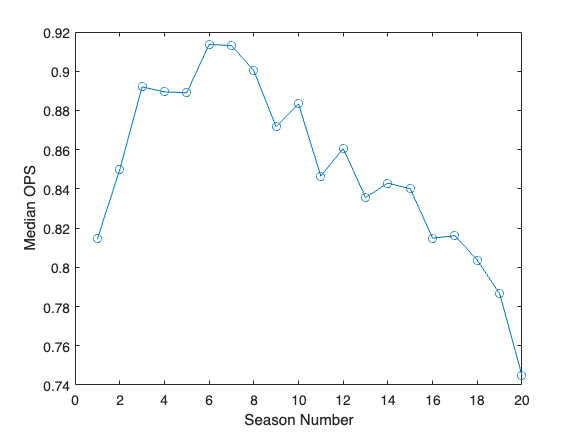

plot(seasonOPS.SeasonNum, seasonOPS.median_OPS, "-o")
xlabel("Season Number")
ylabel("Median OPS")

### Compare Players

players = greatCareers.Name

players = 154×1 string array
    "Hank Aaron"
    "Bobby Abreu"
    "Jose Abreu"
    "Joe Adcock"
    "Dick Allen"
    "Moises Alou"
    "Nolan Arenado"
    "Jeff Bagwell"
    "Ernie Banks"
    "Jose Bautista"
    "Jason Bay"
    "Albert Belle"
    "Carlos Beltran"
    "Lance Berkman"
    "Mookie Betts"
    "Dante Bichette"
    "Charlie Blackmon"
    "Wade Boggs"
    "Barry Bonds"
    "Ryan Braun"
    "George Brett"
    "Kris Bryant"
    "Jay Buhner"
    "Ellis Burks"
    "Pat Burrell"
    "Miguel Cabrera"
    "Robinson Cano"
    "Jose Canseco"
    "Rico Carty"
    "Norm Cash"


### **Adding the player 1 and player 2 to the Median graph created above.**

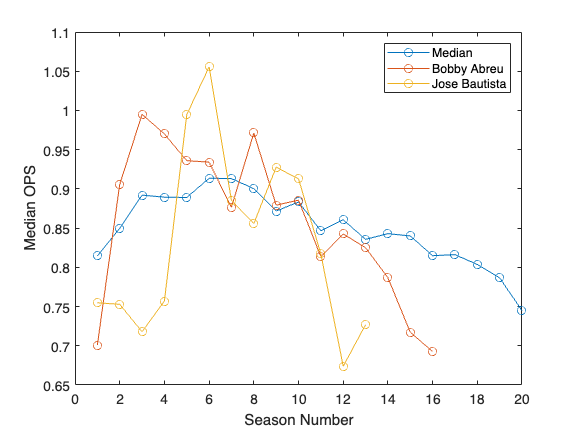

greatCareers = 154×23 table
    playerID           Name            OPS        AVG        SLG        OBP       G       AB       R       H      x2B    x3B    HR     RBI     SB     CS      BB      SO     IBB    HBP    SH    SF     GIDP
    _________    ________________    _______    _______    _______    _______    ____    _____    ____    ____    ___    ___    ___    ____

player1 = players(2);
player2 = players(10);

player1Stats = greatHitters(greatHitters.Name == player1, :);
player2Stats = greatHitters(greatHitters.Name == player2, :);

plot(seasonOPS.SeasonNum, seasonOPS.median_OPS, "-o")
xlabel("Season Number")
ylabel("Median OPS")

hold on
plot(player1Stats.SeasonNum, player1Stats.OPS, "-o")
plot(player2Stats.SeasonNum, player2Stats.OPS, "-o")
hold off
legend(["Median", player1, player2])